# SMR 실습

## <데이터 분석>

### 1. 데이터 불러오기

### 2. 전처리

CAR (전체 평균 뇌파 제외하여 잡음 제거)

Epoching (이벤트에 따라 클래스별로 에포킹) -> 4차원 data

Artifact Reject (아티펙트 제거, 잡음이 있는 Trials 제거)

- [https://www.cmu.edu/dietrich/psychology/memorylab/EEG/artifact_reject.html](https://www.cmu.edu/dietrich/psychology/memorylab/EEG/artifact_reject.html)  

### 3. Time-frequency 분석

한 채널 / 모든 채널 / FTF분석

### 4. Topography

특정 구간의 데이터의 평균값을 모든 채널에 대해 구하여 이미지화

## <Training>

### 1. 데이터 불러오기

### 2. 전처리

CAR (전체 평균 뇌파 제외하여 잡음 제거)

Epoching (이벤트에 따라 클래스별로 에포킹) -> 4차원 data

Artifact Reject (아티펙트 제거, 잡음이 있는 Trials 제거)

- [https://www.cmu.edu/dietrich/psychology/memorylab/EEG/artifact_reject.html](https://www.cmu.edu/dietrich/psychology/memorylab/EEG/artifact_reject.html)  

### 3. 특징 추출

band-pass 필터링 (특정 주파수 사이의 신호만 통과)

power calculation (신호 제곱, 전체 시간에 대해 평균)

데이터 시각화

### 4. 학습

Labeling ([traials x channels] [0/1])

분류 학습 (SVM)

## <Test>

### 1. 데이터 불러오기

### 2. 전처리

CAR (전체 평균 뇌파 제외하여 잡음 제거)

Epoching (이벤트에 따라 클래스별로 에포킹) -> 4차원 data

(생략)

### 3. 특징 추출

band-pass 필터링 (특정 주파수 사이의 신호만 통과)

power calculation (신호 제곱, 전체 시간에 대해 평균)

데이터 시각화

### 4. 예측

Labeling ([traials x channels] [0/1])

*EEGLAB 사용하여 논문 쓸 때 각주

: Delorme A & MAkeing S (2004) EEGLAB: an open-source toolbox for analysis of single-trial EEG dynamics, Journal od Neuroscience Methods 134:9-21

[http://gigadb.org/dataset/view/id/100542/File_page/15](http://gigadb.org/dataset/view/id/100542/File_page/15)    "sess01_subj36_EEG_MI.mat"

: Min-Ho Lee et al., "EEG Dataset and OpenBMI Toolbox for Three BCI Paradigms: An Investigation into BCI Illiteracy", GigaScience, 8, 2019, 1-16

# 데이터 설명

sampling rate: 1,000Hz (1초에 1000번 데이터 측정)

EEG 채널: 62 채널 (62군데에서 데이터를 측정)

Reference: nasion

Ground: Afz (코의 움푹 들어간 부분)

Task: 각 손을 움켜쥐는 움직이는 상상

Trials: 100 (trainig, test 모두, 각 손마다 50개)

시각자극: 3초 Fixation, 4초간 왼쪽 또는 오른쪽 화살표, 6초(+-1.5) 휴식

<데이터 분석>

% %set path
clear all; close all; clc;
addpath(genpath('D:\W00Y0NG\MATLAB\PhDYeom\Ground'))

%parameters 초기화
sf = 1000;                                  % Sampling frequency
ch_n = 62;                                  % Number of channels
wnd_size=[-1 4];                            % Window size
baseline=[-1 0];                            % Baseline
f_scale=1;                                  % Frequency interval for time-frequency analysis
freq_band=[0.1 100];                        % Frequency band for time-frequency analysis
normal=1;                                   % Normalization by the baseline
fullscreen=get(0,'ScreenSize');             % Size of the monitor screen
[position]=EEG_62ch_layout_Brain_Products;  % EEG channel positions

%데이터 불러오기
load('sess01_subj36_EEG_MI.mat');

%x: EEG 채널(Time*Channel)
%t: 이벤트 시간
%y_dec: 이벤트 타입 (1,2)
%y_logic: 이벤트 타입 (0,1)
%y_class: 이벤트 타입
%chan: 채널
%EMG: EMG(Time*Channel)

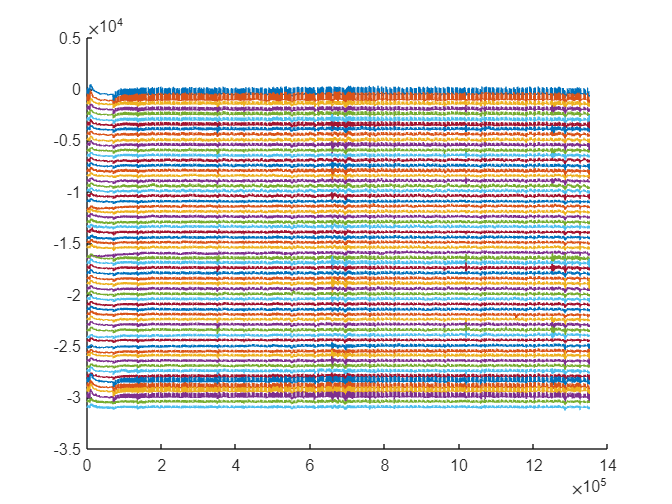

%모든 데이터 plotting
EEG = EEG_MI_train.x'; %행열 변환
EMG = EEG_MI_train.EMG';

figure; hold on;
for ch = 1 : ch_n
    plot(EEG(ch, :) - ch*500) %신호 간격 = 500
end

%CAR
EEG = EEG - repmat(mean(EEG, 1), ch_n, 1);

events{1}=EEG_MI_train.t(find(EEG_MI_train.y_dec==1)); % 오른손
events{2}=EEG_MI_train.t(find(EEG_MI_train.y_dec==2)); % 왼손

for i=1:length(events)         % Class number
    for tr=1:size(events{i},2) % Trials number 
        e_EEG{i}(:,:,tr) = EEG(:,round(events{i}(tr)+(wnd_size(1)*sf)):round(events{i}(tr)+(wnd_size(2)*sf)));
        e_EMG{i}(:,:,tr) = EMG(:,round(events{i}(tr)+(wnd_size(1)*sf)):round(events{i}(tr)+(wnd_size(2)*sf)));
    end
end

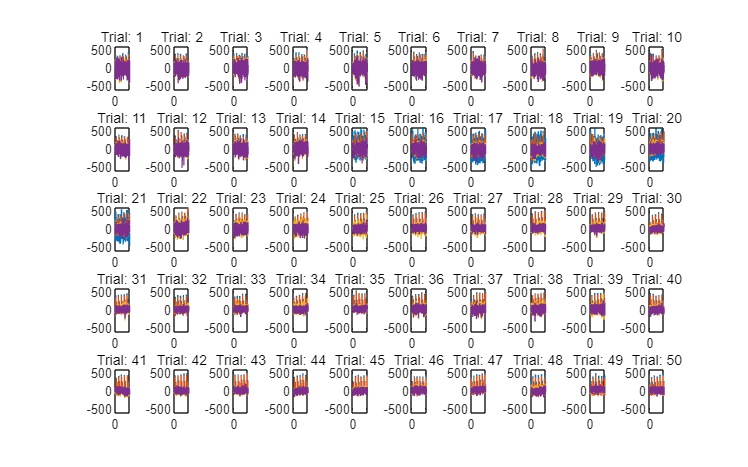

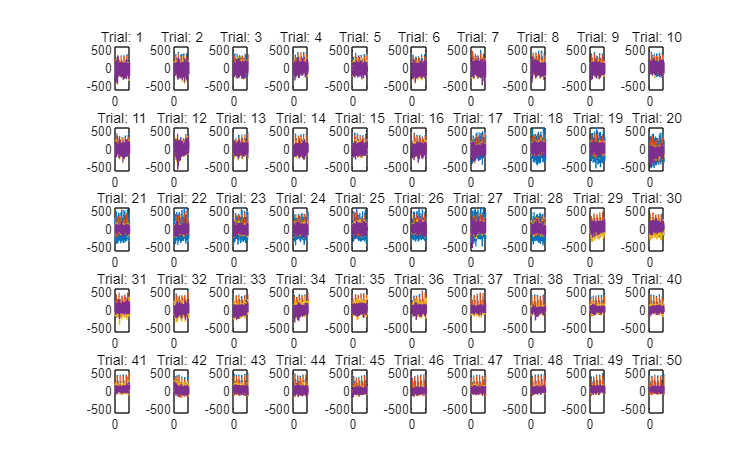

% Plotting EMG signals
for i=1:length(events)
    figure('Position',[0 0 fullscreen(3) fullscreen(4)]); % New window
    for tr=1:size(e_EEG{i},3)
        subplot(5,10,tr);                                 % Plotting the figure at tr-th on 5*10 matrix 
        plot(e_EMG{i}(:,:,tr)');                          % Plotting EMG of tr-th trial and i-th task
        ylim([-600 600]);                                 % Limitation of the y-axis
        title(['Trial: ', num2str(tr)]);                  % Title of the figure
    end
end

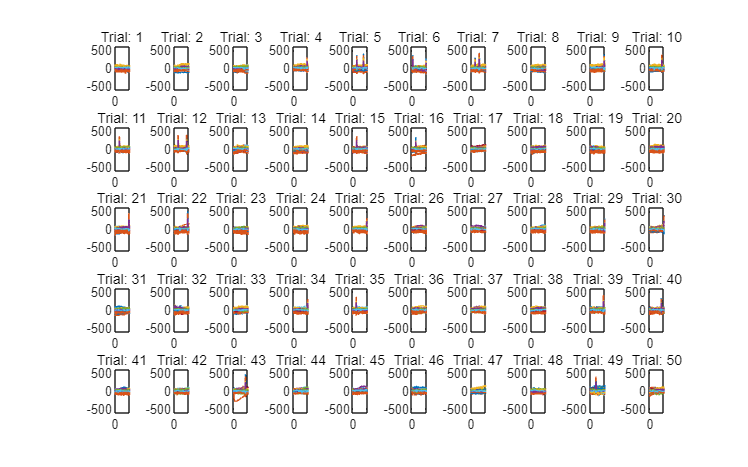

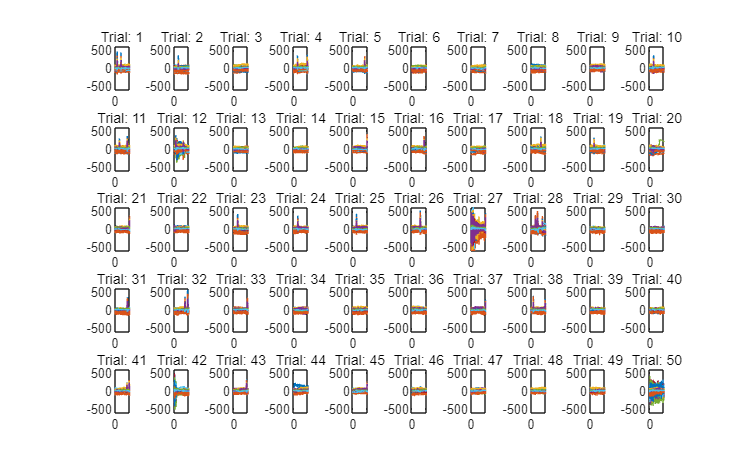



% Plotting EEG signals
for i=1:length(events)
    figure('Position',[0 0 fullscreen(3) fullscreen(4)]); % New window
    for tr=1:size(e_EEG{i},3)
        subplot(5,10,tr);                 % Plotting the figure at j-th on 5*10 matrix 
        plot(e_EEG{i}(:,:,tr)');          % Plotting EMG of tr-th trial and i-th task
        ylim([-600 600]);                 % Limitation of the y-axis
        title(['Trial: ', num2str(tr)]);  % Title of the figure
    end
end

for i=1:length(events)
    for ch=1:size(e_EEG{i},1)
        for tr=1:size(e_EEG{i},3)
            TF{i}(ch,:,:,tr) = timefreq_anal(e_EEG{i}(ch,:,tr), sf, wnd_size, baseline,f_scale,freq_band, normal);
        end
    end
    fprintf(['Calculation of TF of task ', num2str(i), ' is finished\n']);
end

% Averaging the TF by trials
for i=1:length(events)
    m_TF(:,:,:,i)=squeeze(mean(TF{i},4)); 
end

t=linspace(wnd_size(1),wnd_size(2),size(m_TF,3)); % time
fr=linspace(freq_band(1), freq_band(2),size(m_TF,2)); % frequency

figure('Position',[0 0 fullscreen(3) fullscreen(4)]);
for ch=1:size(e_EEG{i},1)
    subplot('Position', position(ch,:));
    pcolor(t,fr,squeeze(m_TF(ch,:,:,i))); 
    shading 'interp'; caxis([-0.5 0.5]); 
    % Line for Onset time
    x1=[0 0]; y1=freq_band; line(x1,y1,'Color','red', 'LineWidth', 1);    
end
 

t=linspace(wnd_size(1),wnd_size(2),size(m_TF,3)); % time
fr=linspace(freq_band(1), freq_band(2),size(m_TF,2)); % frequency

figure('Position',[0 0 fullscreen(3) fullscreen(4)]);
for ch=1:size(e_EEG{i},1)
    subplot('Position', position(ch,:));
    pcolor(t,fr,squeeze(m_TF(ch,:,:,i))); 
    shading 'interp'; caxis([-0.5 0.5]); 
    % Line for Onset time
    x1=[0 0]; y1=freq_band; line(x1,y1,'Color','red', 'LineWidth', 1);    
end

bpf=[8 26];                   % 8~26Hz
dur=([0 4]-wnd_size(1))*sf;   % 0~4 sec
for i=1:length(events)
    TP(:,i)=mean(mean(m_TF(:,bpf(1):bpf(2),dur(1):dur(2),i),3),2);
end
 
figure;
for i=1:length(events)
    subplot(1,4,i);topoplot(TP(:,i), 'Standard-10-20-Cap62_Brain_Products.locs','style','map', 'maplimits', [-0.3 0.3], 'whitebk','on', 'plotrad',0.548, 'headrad',0.5, 'shading','interp');
end

bpf=[8 26];                   % Frequency for the band-pass filtering
dur=([0 4]-wnd_size(1))*sf;   % Duration for the feature extraction

for i=1:length(events)
    for ch=1:size(e_EEG{i},1)
        for tr=1:size(e_EEG{i},3)
            fil_EEG{i}(ch, :, tr)=bandpass(e_EEG{i}(ch, dur(1):dur(2), tr), bpf, sf); % Band-pass filtering
            P{i}(ch,tr)=mean(fil_EEG{i}(ch, :, tr).^2);                             % Power calculation
        end
    end
end

% Examining the data on the 13, 15 channels
figure; i=1; plot(P{i}(13,:),P{i}(15,:),'*'); hold on; i=2; plot(P{i}(13,:),P{i}(15,:),'ro');

% Labeling the data
X_tr=[P{1}'; P{2}'];
Y_tr=[zeros(size(P{1},2),1); ones(size(P{2},2),1)];

% Training the SVM model
SVMModel = fitcsvm(X_tr,Y_tr,'KernelScale','auto','Standardize',true);


EEG_ts = EEG_MI_test.x';  % For short name 
EEG_ts = EEG_ts-repmat(mean(EEG_ts,1), ch_n,1);

events_ts {1}=EEG_MI_test.t(find(EEG_MI_test.y_dec==1)); % right hand
events_ts {2}=EEG_MI_test.t(find(EEG_MI_test.y_dec==2)); % left hand

for i=1:length(events_ts)         % Class number
    for tr=1:size(events_ts{i},2) % Trials number 
        e_EEG_ts{i}(:,:,tr) = EEG_ts(:,round(events_ts{i}(tr)+(wnd_size(1)*sf)):round(events_ts{i}(tr)+(wnd_size(2)*sf)));
    end
end

for i=1:length(events_ts)
    for ch=1:size(e_EEG_ts{i},1)
        for tr=1:size(e_EEG_ts{i},3)
            fil_EEG_ts{i}(ch, :, tr)=bandpass(e_EEG_ts{i}(ch, dur(1):dur(2), tr), bpf, sf); % Band-pass filtering
            P_ts{i}(ch,tr)=mean(fil_EEG_ts{i}(ch, :, tr).^2);                             % Power calculation
        end
    end
end

% Examining the data
figure; i=1; plot(P_ts{i}(13,:),P_ts{i}(15,:),'*'); hold on; i=2; plot(P_ts{i}(13,:),P_ts{i}(15,:),'ro');

% Labeling the data
X_ts=[P_ts{1}'; P_ts{2}'];
Y_ts=[zeros(size(P_ts{1},2),1);ones(size(P_ts{2},2),1)];

% Prediction
label= predict(SVMModel, X_ts); 

% Accuracy
accuracy=(1-loss(SVMModel, X_ts, Y_ts))*100
